# [Solution] DMRG: Two-site update for ground state search

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

## Solution to Exercise (a): Complete the two-site DMRG function

Check out the funciton `DMRG_GS_2site.m` under the `DMRG` sub-directory. Compare with your implementation of `DMRG_GS_2site_Ex.m`!

## Solution to Exercise (b): Majumdar-Ghosh model

We first construct the MPO Hamiltonian for the Majumdar-Ghosh model,


$$\hat{H} = \sum_{\ell=1}^{L-1} \hat{\vec{S}}_\ell \cdot \hat{\vec{S}}_{\ell+1} + \frac{1}{2} \sum_{\ell=1}^{L-2} \hat{\vec{S}}_\ell \cdot \hat{\vec{S}}_{\ell+2} .$$


clear

% system parameter
J1 = 1; % nearest-neighbour coupling strength
J2 = 1/2; % next-nearest-neighbour coupling strength
L = 40; % number of sites in a chain

% DMRG parameter
Nkeep = 30; % bond dimension
Nsweep = 5; % number of pairs of left+right sweeps

% Local operators
[S,I] = getLocalSpace('Spin',1/2);

% Hamiltonian tensor for each chain site
Hloc = cell(8,8);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
Hloc{2,1} = S(:,:,1);
Hloc{3,1} = S(:,:,2);
Hloc{4,1} = S(:,:,3);
Hloc{5,2} = I;
Hloc{6,3} = I;
Hloc{7,4} = I;
Hloc{8,2} = J1*(Hloc{2,1}');
Hloc{8,3} = J1*(Hloc{3,1}');
Hloc{8,4} = J1*(Hloc{4,1}');
Hloc{8,5} = J2*(Hloc{2,1}');
Hloc{8,6} = J2*(Hloc{3,1}');
Hloc{8,7} = J2*(Hloc{4,1}');
Hloc{end,end} = I;
Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));

% full chain
Hs = cell(1,L);
Hs(:) = {Hloc};
Hs{1} = Hs{1}(:,:,end,:); % choose the last components of the left leg
Hs{end} = Hs{end}(:,:,:,1); % choose the first components of the right leg

We define a random MPS as the initial guess. The iterative diagonalization result can be used as well.

Minit = cell(1,L);
Minit{1} = rand(1,Nkeep,size(I,2));
Minit{end} = rand(Nkeep,1,size(I,2));
for itN = (2:L-1)
    Minit{itN} = rand(Nkeep,Nkeep,size(I,2));
end
[M0,E0,Eiter,Sv] = DMRG_GS_2site(Minit,Hs,Nkeep,Nsweep);

22-09-27 13:40:27 | Two-site DMRG: ground state search
22-09-27 13:40:27 | # of sites = 40, Nkeep = 30, # of sweeps = 5 x 2
22-09-27 13:40:28 | Sweep #1/10 (right -> left) : Energy = -14.96546
22-09-27 13:40:28 | Sweep #2/10 (left -> right) : Energy = -15
22-09-27 13:40:28 | Sweep #3/10 (right -> left) : Energy = -15
22-09-27 13:40:29 | Sweep #4/10 (left -> right) : Energy = -15
22-09-27 13:40:29 | Sweep #5/10 (right -> left) : Energy = -15
22-09-27 13:40:29 | Sweep #6/10 (left -> right) : Energy = -15
22-09-27 13:40:29 | Sweep #7/10 (right -> left) : Energy = -15
22-09-27 13:40:29 | Sweep #8/10 (left -> right) : Energy = -15
22-09-27 13:40:29 | Sweep #9/10 (right -> left) : Energy = -15
22-09-27 13:40:29 | Sweep #10/10 (left -> right) : Energy = -15
Elapsed time: 1.785s, CPU time: 12.99s, Avg # of cores: 7.279


E0_exact = -3*L/8; % exact value
disptime(['Exact GS energy = ',sprintf('%.5g',E0_exact),', DMRG = ', ...
    sprintf('%.5g',E0),', error = ',sprintf('%.5g',E0-E0_exact)]);

22-09-27 13:40:29 | Exact GS energy = -15, DMRG = -15, error = 1.954e-14


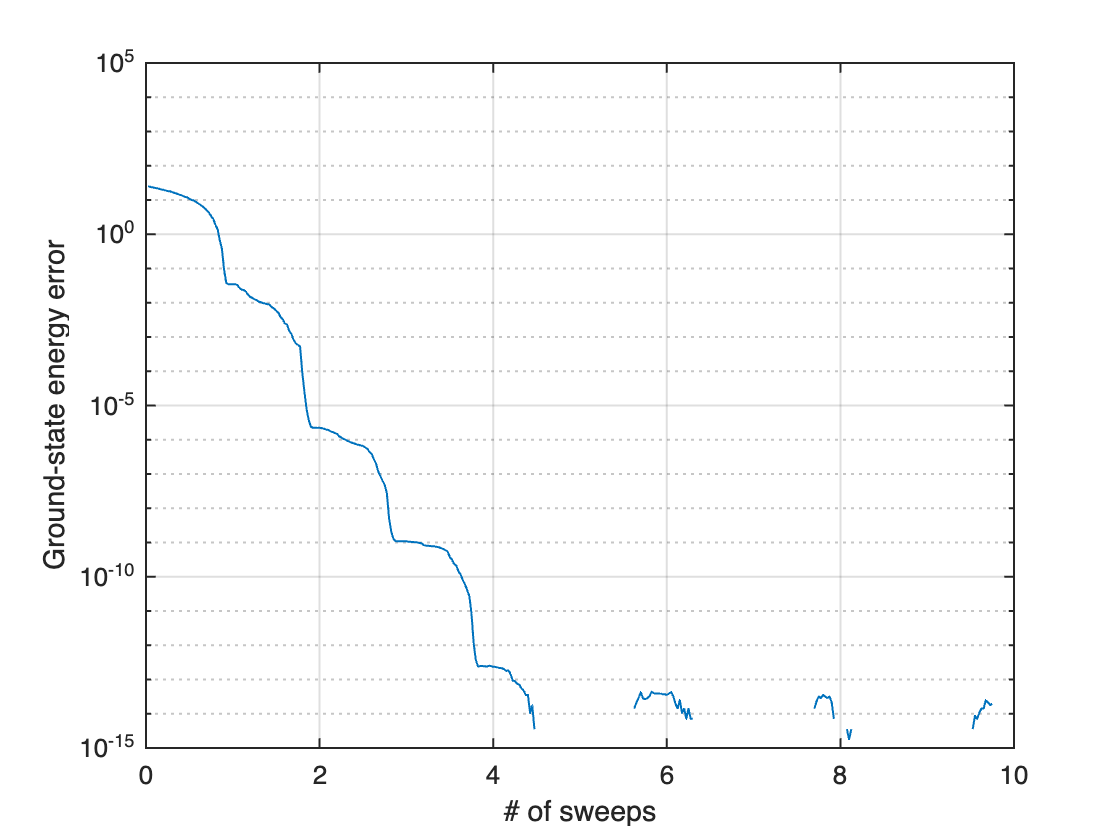

figure;
plot((1:numel(Eiter))/L,Eiter(:)-E0_exact,'LineWidth',1);
set(gca,'XScale','Linear','YScale','log','FontSize',13,'LineWidth',1);
xlim([0 2*Nsweep]);
grid on;
xlabel('# of sweeps');
ylabel('Ground-state energy error');

The error is of the order of double precision.

Let's look at the sizes of the MPS tensors.

M0

M0 = 1×40 cell array
    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}    {1×2×2 double}    {2×1×2 double}


The bond dimensions are oscillating between 1 and 2!

To see what happened, we first plot the singular values on different bonds. Since `Sv{1}` and `Sv{end}` just contain the norm of the MPS, we plot the data for `Sv(2:end-1)`.

% maximum bond dimension
nSv_max = max(cellfun('prodofsize',Sv(2:end-1)))

nSv_max = 2

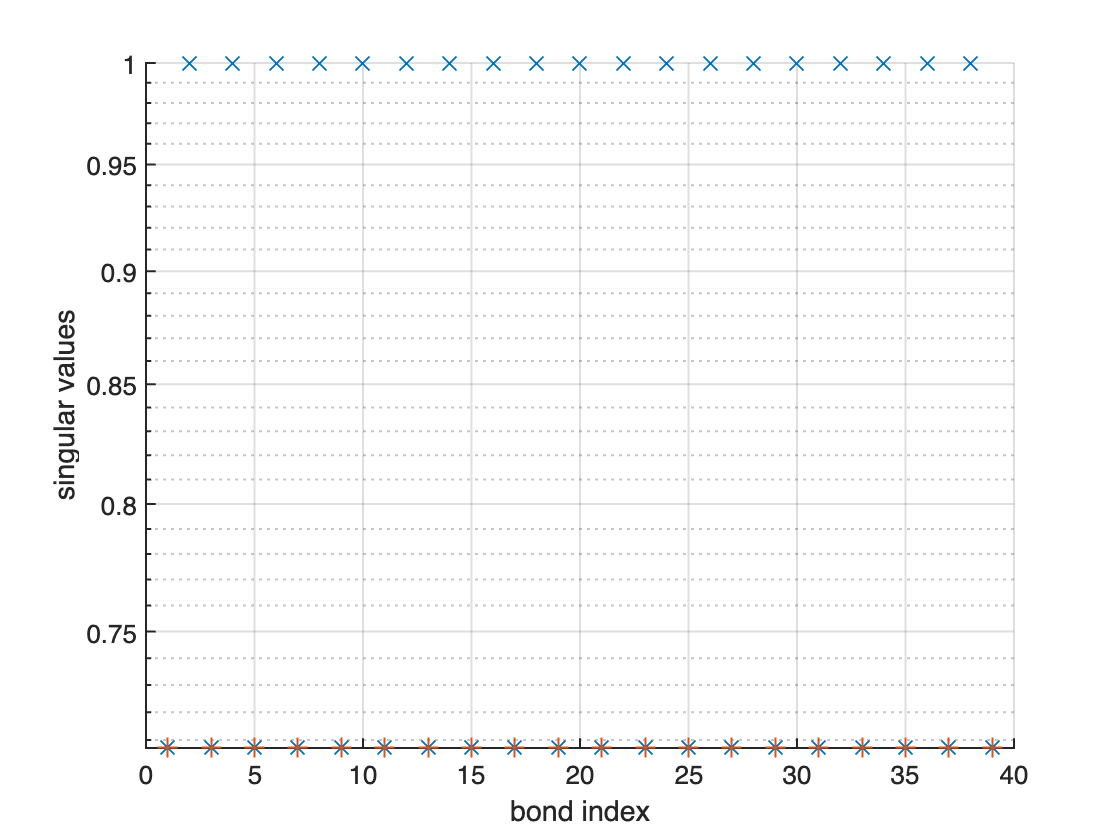

Sv_tot = nan(nSv_max,numel(Sv(2:end-1)));
for itN = (1:size(Sv_tot,2))
    Sv_tot(1:numel(Sv{itN+1}),itN) = Sv{itN+1};
end
figure;
hold on;
plot((1:numel(Sv)-2),Sv_tot(1,:).','x','LineWidth',1,'MarkerSize',10);
plot((1:numel(Sv)-2),Sv_tot(2,:).','+','LineWidth',1,'MarkerSize',10);
hold off;
set(gca,'XScale','Linear','YScale','log','FontSize',13,'LineWidth',1);
grid on;
xlabel('bond index')
ylabel('singular values')

The singular values oscillates, with periodicity 2. On the bond between sites n and n+1 with odd n, the singular values are doubly degenerate, i.e., $(1/\sqrt{2}, 1/\sqrt{2})$:

Sv{2}*sqrt(2)

ans =     1.0000
    1.0000


Meanwhile, on the bond between sites n and n+1 with even n, there is only one singular value which is unity:

Sv{3}

ans = 1

The singleton bond dimension indicates a direct product. That is, the ground state of the Majumdar-Ghosh model is just the direct product of $L/2$ copies of spin singlets. It can be also seen from the spin-spin correlation function $\langle \Psi_0 | \hat{S}_{\ell,+} \hat{S}_{\ell+1,-} | \Psi_0 \rangle$.

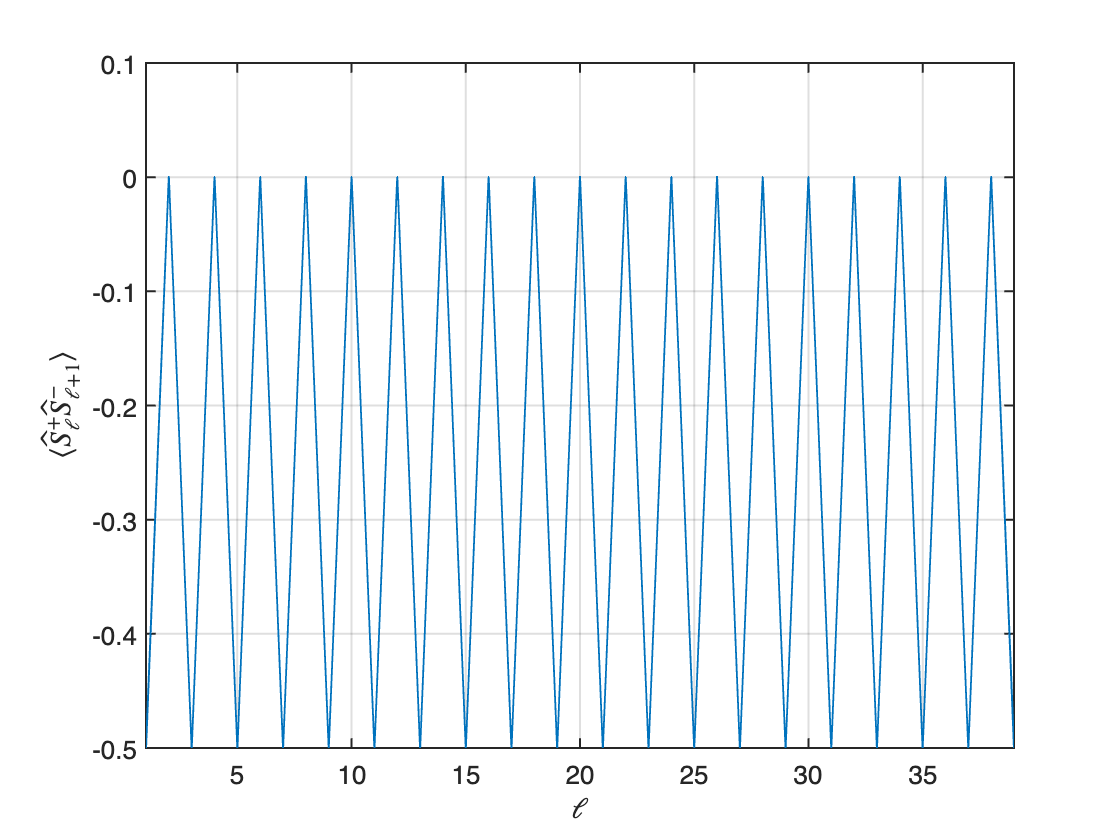

% compute correlation function for the nearest-neighbour spins
SS = zeros(1,L-1);
for itN = (2:L)
    T = updateLeft([],[],M0{itN-1},S(:,:,1)*sqrt(2),3,M0{itN-1});
    T = updateLeft(T,3,M0{itN},S(:,:,3)*sqrt(2),3,M0{itN});
    
    for itN2 = ((itN+1):L)
        T = updateLeft(T,2,M0{itN2},[],[],M0{itN2});
    end
    
    SS(itN-1) = T;
end

figure;
plot((1:L-1),SS,'LineWidth',1);
set(gca,'FontSize',13,'LineWidth',1);
xlabel('$\ell$','Interpreter','latex');
ylabel('$\langle \hat{S}^+_\ell \hat{S}^-_{\ell+1} \rangle$', ...
    'Interpreter','latex');
xlim([1 L-1]);
grid on;